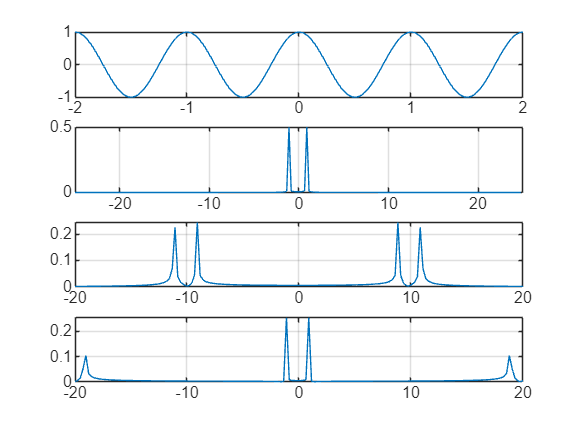

%Q1
t = -2:0.02:2;
fs = 50;
Ts = 1/fs;
L = length(t);
x = cos(2*pi*t);
y = cos(2*pi*t).*cos(20*pi*t);
z = y.*cos(20*pi*t);
f_axis = (-L/2:L/2-1)*(fs/L);

x_fft =fft(x);
x_shifted = fftshift(x_fft);
x_mag = abs(x_shifted/L);

y_fft =fft(y);
y_shifted = fftshift(y_fft);
y_mag = abs(y_shifted/L);

z_fft =fft(z);
z_shifted = fftshift(z_fft);
z_mag = abs(z_shifted/L);


subplot(4,1,1);
plot(t,x)
grid on
xlim([-2,2]);

subplot(4,1,2);
plot(f_axis,x_mag );
grid on
xlim([-25,25]);

subplot(4,1,3);
plot(f_axis,y_mag);
grid on
xlim([-20,20]);

subplot(4,1,4);
plot(f_axis,z_mag);
grid on 
xlim([-20,20]);

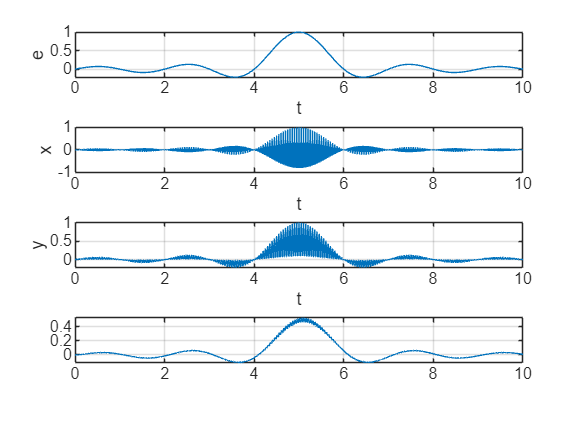

%Q2
t = 0:0.01:10;
Fs = 100;
Ts = 1/Fs;
L = length(t);

e = sin(pi*(t - 5))./(pi*(t - 5));
e(t==5) = 1;
x = e.*cos(80*pi*t);
y = x.*cos(80*pi*t);

num = 10;
den = [1,10];
sys = tf(num,den);
r = lsim(sys,y,t);

f_axis = (-L/2:L/2-1)*(Fs/L);

E_mag = abs(fftshift(fft(e)))/L;
X_mag = abs(fftshift(fft(x)))/L;
Y_mag = abs(fftshift(fft(y)))/L;
R_mag = abs(fftshift(fft(r)))/L;

figure
subplot(4,1,1);
plot(t,e);
xlabel('t');
ylabel('e');
grid on;

subplot(4,1,2);
plot(t,x)
xlabel('t');
ylabel('x');
grid on;

subplot(4,1,3);
plot(t,y);
xlabel('t');
ylabel('y');
grid on;

subplot(4,1,4);
plot(t,r);
grid on;

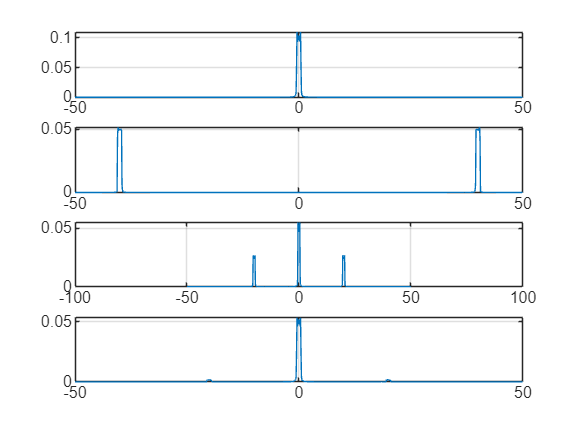


figure
subplot(4,1,1);
plot(f_axis, E_mag);
grid on;
xlim([-50 50]);

subplot(4,1,2);
plot(f_axis, X_mag);
grid on;
xlim([-50 50]);

subplot(4,1,3);
plot(f_axis, Y_mag);
grid on; xlim([-100 100]);

subplot(4,1,4);
plot(f_axis, R_mag);
grid on;
xlim([-50 50]);

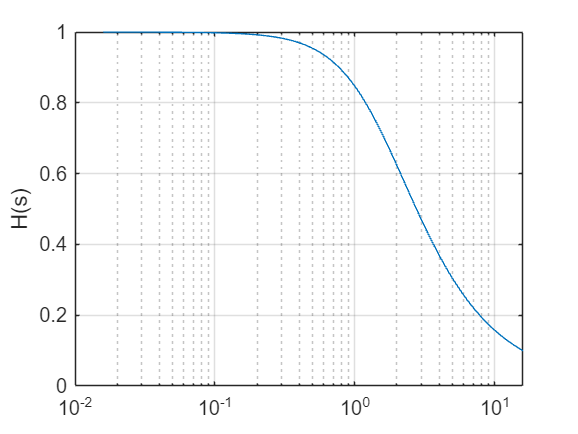


figure
w = logspace(-1, 2, 500); 


[h, ~] = freqs(num, den, w); 


mag_h = abs(h);
f_h = w / (2*pi); 
semilogx(f_h, mag_h); 
grid on
ylabel('H(s)的幅频')

%H（s）是个低频滤波器，用于提取还原解调后的信号

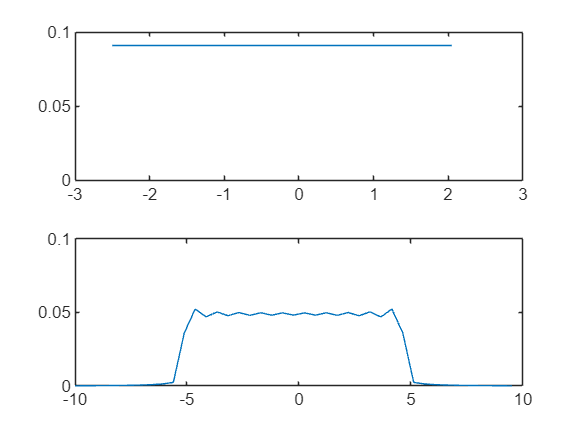

%Q3(1)
Ts = 0.2;
Fs = 1/Ts;
t = -1:Ts:1;
L = length(t);
f_axis = (-L/2:L/2-1)*(Fs/L);
y = sin(10*pi*t)./(10*pi*t);
y(t == 0) = 1;
y_fft = fft(y);
y_shifted = fftshift(y_fft);
y_mag = abs(y_shifted)/L;

subplot(2,1,1);
plot(f_axis,y_mag);
ylim([0,0.1])

%Q3(2)
Ts = 0.05;
Fs = 1/Ts;
t = -1:Ts:1;
L = length(t);
f_axis = (-L/2:L/2-1)*(Fs/L);
y = sin(10*pi*t)./(10*pi*t);
y(t == 0) = 1;
y_fft = fft(y);
y_shifted = fftshift(y_fft);
y_mag = abs(y_shifted)/L;

subplot(2,1,2);
plot(f_axis,y_mag);
ylim([0,0.1])

%第一个抽样频率太小（5Hz）小于奈奎斯特频率因此频谱发生重叠最终形成平行线